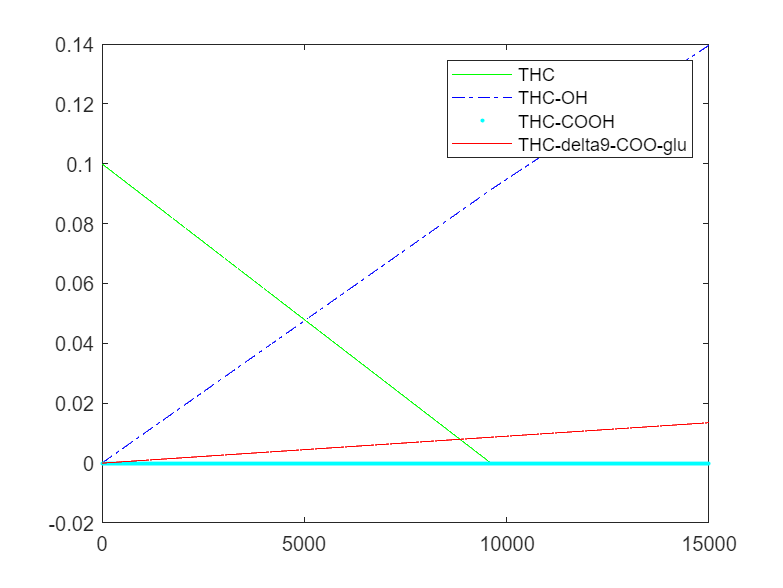

clear
clc
tspan = [0, 15000]; %单位为s
% [THC, 11-OH-THC, THC-COOH, THC-COO-glu]
y0 = [0.1, 0, 0, 0];
[T, X] = ode45(@odefun, tspan, y0);
plot(T, X(:, 1), 'g-', T, X(:, 2), 'b-.', T, X(:, 3), 'c.', T, X(:, 4), 'r-')
legend('THC', 'THC-OH', 'THC-COOH', 'THC-delta9-COO-glu')

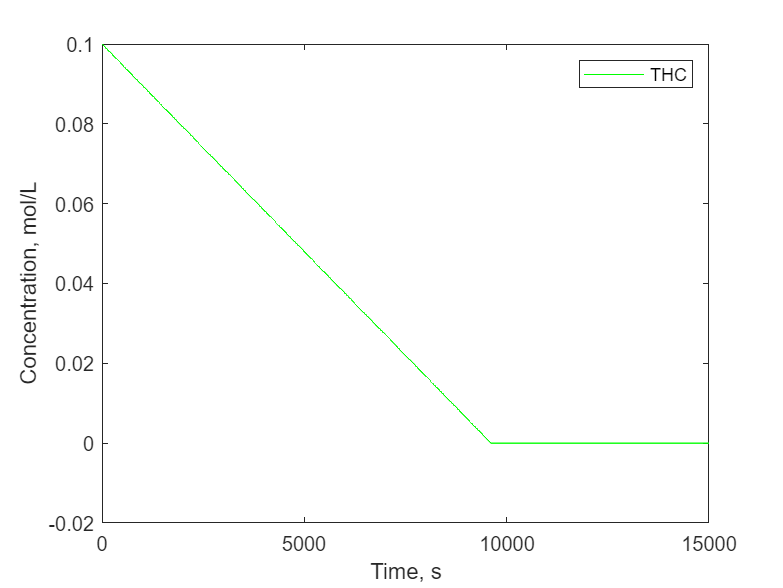

plot(T, X(:, 1), 'g-')
xlabel("Time, s")
ylabel("Concentration, mol/L")
legend('THC')

function dx = odefun(t, x)
m1 = 1;% CYP2C9 mol/L
m2 = 1;% CYP2C9 mol/L
% (Km3, Vm3) = (68, 0.68) or (118.3, 1.10) or (77.1, 2.27)
Km1 = 0.07*1e-6; Km2 = 0.50*1e-6; Km3 = 77.1*1e-6;% uM
% suppose that density of THC solution = pure water
Vm1 = 0.624/60*1e6*1e-9; Vm2 = 0.054/60*1e6*1e-9; Vm3 = 2.27/60*1e6*1e-9;%nmol/s/mg -> mol/L/s protein
dx = zeros(4, 1);    
dx(1) = (-(Vm1*x(1)/(Km1+x(1)))*m1)*(x(1) > (Vm1*x(1)/(Km1+x(1)))*m1);
dx(2) = (Vm1*x(1)/(Km1+x(1)))*m1-(Vm2*x(2)/(Km2+x(2)))*m1;
dx(3) = Vm2*x(2)/(Km2+x(2))*m1-(Vm3*x(3)/(Km3+x(3)))*m2;
dx(4) = Vm3*x(3)/(Km3+x(3))*m2; 
end

